# Simulating IBM's Q Experience in Matlab

## Class [`ibmqx`](matlab:doc('ibmqx')) of FockBox

[*Matthias Wolff*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/prof-dr-ing-habil-matthias-wolff)

[BTU Cottbus-Senftenberg](https://www.b-tu.de/en/), [Chair of Communications Enginerring](https://www.b-tu.de/en/fg-kommunikationstechnik)

August 22, 2018

fock.addFockBoxPaths();

## 1   Introduction

I assume that you are familiar with the fundamentals of quantum computing. If not, you find a good introduction in IBM's Q Experience [1] tutorials (pages may not display correctly in Matlab's web browser):

- [https://quantumexperience.ng.bluemix.net/qx/tutorial?sectionId=beginners-guide](https://quantumexperience.ng.bluemix.net/qx/tutorial?sectionId=beginners-guide) and

- [https://quantumexperience.ng.bluemix.net/qx/tutorial?sectionId=full-user-guide](https://quantumexperience.ng.bluemix.net/qx/tutorial?sectionId=full-user-guide).

FockBox' [2] [`ibmqx`](matlab:doc('ibmqx')) class is a library of constants and static methods helping to simulate quantum computing on IBM Q Experience in Matlab.

**1.1   Quantum States**

*1.1.1   Single-Qubit States*

Qubits can be in a *zero state*

      $|0\rangle\doteq\pmatrix{ 1 \cr 0 }$,

b0 = ibmqx.b0; ibmqx.disp(b0); % disp(b0) displays the underlying fockobj

  ibmqx quantum state

    Name  : |0>
    Qubits: 1

    |0>   1
    |1>   0


a *one state*

      $|1\rangle\doteq\pmatrix{ 0 \cr 1 }$,

b1 = ibmqx.b1; ibmqx.disp(b1);

  ibmqx quantum state

    Name  : |1>
    Qubits: 1

    |0>   0
    |1>   1


or in a *superposition* 

      $|\psi\rangle = a\,|0\rangle + b\,|1\rangle$   with $a,b\in\mathbb{C}$ and $\langle\psi|\psi\rangle=|a|^2+|b|^2=1$

of the two. Hence, the state $|\psi\rangle$ of a qubit is a vector in a two-dimensional vector space with the basis $B=\{|0\rangle,|1\rangle\}$over the field of complex numbers

      $\mathcal{H}
=\mathrm{span}(|0\rangle,|1\rangle)
\doteq\mathbb{C}^2$.

For example:

      
$$|\psi\rangle
= \frac{1}{\sqrt{2}}|0\rangle + \frac{1+\mathrm{i}}{2}|1\rangle
\doteq\pmatrix{
  \frac{1}{\sqrt{2}} \cr
  \frac{1+\mathrm{i}}{2}
}$$


B   = ibmqx.basis;                    disp(B);         % Ignore the epsilon basis vector :)

  fockbasis

    Dimensions: 3
    Sectors   : 2
    Type      : canonical

    ε                   	1
    0                   	2
    1                   	3


psi = 1/sqrt(2)*b0 + 1/2*(1-1i)*b1;   ibmqx.disp(psi); % disp(psi) displays the underlying fockobj

  ibmqx quantum state

    Qubits: 1

    |0>   0.7071
    |1> 0.5-0.5i


fprintf('  <psi|psi> = %g',psi'*psi);

  <psi|psi> = 1

For simulating quantum circuits, we will only use the $|0\rangle$ state explicitly for the preparation of qubits. Everything else will be done with quantum gates.

*1.1.2   Multi-Qubit States*

A quantum circuit works with $N$ qubits denoted by $q[N-1]$, ..., $q[0]$. Its state is a vector in the $N$-fold tensor product of $\mathcal{H}$

      
$$|\psi\rangle \in \mathcal{H}^{\otimes N} = \bigotimes_{i=1}^N\mathcal{H}$$


A multi-qubit state comprising$N$ *independent* single-qubit states $|\psi_{N-1}\rangle,\ldots,|\psi_0\rangle$ can be expressed by a tensor product

      $|\psi\rangle = |\psi_{N-1}\rangle\otimes\ldots\otimes|\psi_0\rangle =: |\psi_{N-1}\ldots\psi_{0}\rangle$.

For instance, we can define the three-qubit zero state by

      
$$|000\rangle = |0\rangle^{\otimes 3} = \bigotimes_{i=1}^3 |0\rangle$$


psi = [b0 b0 b0]; psi.name='|000>';
ibmqx.disp(psi);

  ibmqx quantum state

    Name  : |000>
    Qubits: 3

    |000>     1
    |001>     0
    |010>     0
    |011>     0
    |100>     0
    |101>     0
    |110>     0
    |111>     0


If a multi-qubit state cannot be expressed by a tensor product of single-qubit states, the qubits are called *entangled*. A simple example for an entangled two-qubit state is

      
$$\psi = \frac{1}{\sqrt{2}}(|00\rangle+|11\rangle)$$


psi = 1/sqrt(2)*([b0 b0]+[b1 b1]); psi.name = 'entangled';
ibmqx.disp(psi);

  ibmqx quantum state

    Name  : entangled
    Qubits: 2

    |00> 0.7071
    |01>      0
    |10>      0
    |11> 0.7071


*1.1.3   Qubit State Probabilities and Projection*

Let's come back to the general definition of a single-qubit state $|\psi\rangle = a\,|0\rangle + b\,|1\rangle$ with $a,b\in\mathbb{C}$ and $|a|^2+|b|^2=1$. The quantities $|a|^2$ and $|b|^2$ can be interpreted as the probabilies of the qubit falling into the states $|0\rangle$ and $|1\rangle$, respectively, when *measured* (see below):

      $p_{|0\rangle} = |a|^2$: probability of qubit falling into state $|0\rangle$ when measured, short: *projection probability* of state $|0\rangle$,

      $p_{|1\rangle}=|b|^2$: probability of qubit being into state $|1\rangle$ when measured, short: *projection probability* of state $|1\rangle$.

This is reasonable because $1=|a|^2+|b|^2=p_{|0\rangle}+p_{|1\rangle}$ holds. Rewriting $p_{|1\rangle}=:p$ and $p_{|0\rangle}=1-p$ we can prepare a qubit with the projection probability $p$ of state $|1\rangle$ as

      $|\psi_p\rangle = \sqrt{1-p}|0\rangle + \sqrt{p}|1\rangle$.

For example:

p   = 0.8;
psi = sqrt(1-p)*b0 + sqrt(p)*b1; psi.name = 'p(|1>)=0.8';
ibmqx.disp(psi);

  ibmqx quantum state

    Name  : p(|1>)=0.8
    Qubits: 1

    |0> 0.4472
    |1> 0.8944


In order to retrieve the projection probabilities from the qubit state, we define *projectors*

      $P_{|0\rangle} = |0\rangle\langle 0|$ and $P_{|1\rangle} = |1\rangle\langle 1|$

and apply them to the qubit state 

      $p_{|0\rangle} = \langle\psi|P_{|0\rangle}|\psi\rangle\$ and $p_{|1\rangle} = \langle\psi|P_{|1\rangle}|\psi\rangle$.

P0 = b0*b0'; P0.name = 'projector on |0>'; ibmqx.disp(P0);

  ibmqx quantum gate operator

    Name  : projector on |0>
    Qubits: 1

        <0| <1|
    |0>   1   0
    |1>   0   0


P1 = b1*b1'; P1.name = 'projector on |1>'; ibmqx.disp(P1);

  ibmqx quantum gate operator

    Name  : projector on |1>
    Qubits: 1

        <0| <1|
    |0>   0   0
    |1>   0   1


fprintf('p(|0>) = %g\n',psi'*P0*psi);

p(|0>) = 0.2


fprintf('p(|1>) = %g\n',psi'*P1*psi);

p(|1>) = 0.8


The principle can be extended to multi-qubit states, e.g. for two qubits $q[1]$ and $q[0]$:

      $p_{|00\rangle}$: joint probability of $q[1]$ falling into state $|0\rangle$*and* $q[0]$ falling into  state $|0\rangle$ with projector $P_{|00\rangle}=|00\rangle\langle 00|$,

      $p_{|01\rangle}$: joint probability of $q[1]$ falling into state $|0\rangle$*and* $q[0]$ falling into state $|1\rangle$ with projector $P_{|01\rangle}=|01\rangle\langle 01|$,

      $p_{|10\rangle}$: joint probability of $q[1]$ falling into state $|1\rangle$*and* $q[0]$ falling into state $|0\rangle$ with projector $P_{|10\rangle}=|10\rangle\langle 10|$, and

      $p_{|11\rangle}$: joint probability of $q[1]$ falling into state $|1\rangle$*and* $q[0]$ falling into state $|1\rangle$ with projector $P_{|11\rangle}=|11\rangle\langle 11|$.

Of course, $p_{|00\rangle}+p_{|01\rangle}+p_{|10\rangle}+p_{|11\rangle}=1$ must hold. Let's use, for example, $p_{|00\rangle}=0.5$, $p_{|01\rangle}=0.3$, $p_{|10\rangle}=0$, and $p_{|11\rangle}=0.2$:

p00 = 0.5; p01 = 0.3; p10 = 0; p11 = 0.2;
psi = sqrt(p00)*[b0 b0] + sqrt(p01)*[b0 b1] + sqrt(p10)*[b1 b0] + sqrt(p11)*[b1 b1]; 
ibmqx.disp(psi);

  ibmqx quantum state

    Qubits: 2

    |00> 0.7071
    |01> 0.5477
    |10>      0
    |11> 0.4472



P00 = [b0 b0]*[b0 b0]'; P00.name = 'projector on |00>'; ibmqx.disp(P00);

  ibmqx quantum gate operator

    Name  : projector on |00>
    Qubits: 2

         <00| <01| <10| <11|
    |00>    1    0    0    0
    |01>    0    0    0    0
    |10>    0    0    0    0
    |11>    0    0    0    0


P01 = [b0 b1]*[b0 b1]'; P01.name = 'projector on |01>'; ibmqx.disp(P01);

  ibmqx quantum gate operator

    Name  : projector on |01>
    Qubits: 2

         <00| <01| <10| <11|
    |00>    0    0    0    0
    |01>    0    1    0    0
    |10>    0    0    0    0
    |11>    0    0    0    0


P10 = [b1 b0]*[b1 b0]'; P10.name = 'projector on |10>'; ibmqx.disp(P10);

  ibmqx quantum gate operator

    Name  : projector on |10>
    Qubits: 2

         <00| <01| <10| <11|
    |00>    0    0    0    0
    |01>    0    0    0    0
    |10>    0    0    1    0
    |11>    0    0    0    0


P11 = [b1 b1]*[b1 b1]'; P11.name = 'projector on |11>'; ibmqx.disp(P11);

  ibmqx quantum gate operator

    Name  : projector on |11>
    Qubits: 2

         <00| <01| <10| <11|
    |00>    0    0    0    0
    |01>    0    0    0    0
    |10>    0    0    0    0
    |11>    0    0    0    1


fprintf('p(|00>) = %g\n',psi'*P00*psi);

p(|00>) = 0.5


fprintf('p(|01>) = %g\n',psi'*P01*psi);

p(|01>) = 0.3


fprintf('p(|10>) = %g\n',psi'*P10*psi);

p(|10>) = 0


fprintf('p(|11>) = %g\n',psi'*P11*psi);

p(|11>) = 0.2


If we only care for the projection probabilities of one of the cubits, we can exclude the other by adding its two projectors, e.g.,

      $P_{q[0]=|0\rangle} = P_{|00\rangle} + P_{|10\rangle}$: projector for getting the probability of $q[0]=|0\rangle$ only, $p_{q[0]=|0\rangle}=p_{|00\rangle}+p_{|10\rangle}=\langle\psi|P_{q[0]=|0\rangle}|\psi\rangle$,

      $P_{q[0]=|1\rangle} = P_{|01\rangle} + P_{|11\rangle}$: projector for getting the probability of $q[0]=|1\rangle$ only, $p_{q[0]=|1\rangle}=p_{|01\rangle}+p_{|11\rangle}=\langle\psi|P_{q[0]=|1\rangle}|\psi\rangle$,

      $P_{q[1]=|0\rangle} = P_{|00\rangle} + P_{|01\rangle}$: projector for getting the probability of $q[1]=|0\rangle$ only, $p_{q[1]=|0\rangle}=p_{|00\rangle}+p_{|01\rangle}=\langle\psi|P_{q[1]=|0\rangle}|\psi\rangle$, and

      $P_{q[1]=|1\rangle} = P_{|10\rangle} + P_{|11\rangle}$: projector for getting the probability of $q[1]=|1\rangle$ only, $p_{q[1]=|1\rangle}=p_{|10\rangle}+p_{|11\rangle}=\langle\psi|P_{q[1]=|1\rangle}|\psi\rangle$.

fprintf('p(q[0]=|0>) = %g\n',psi'*(P00+P10)*psi);

p(q[0]=|0>) = 0.5


fprintf('p(q[0]=|1>) = %g\n',psi'*(P01+P11)*psi);

p(q[0]=|1>) = 0.5


fprintf('p(q[1]=|0>) = %g\n',psi'*(P00+P01)*psi);

p(q[1]=|0>) = 0.8


fprintf('p(q[1]=|1>) = %g\n',psi'*(P10+P11)*psi);

p(q[1]=|1>) = 0.2


Of course, $p_{q[1]=|0\rangle}
+p_{q[1]=|1\rangle}
=1$ and $p_{q[0]=|0\rangle}
+p_{q[0]=|1\rangle}
=1$ hold. By the way, our example two-qubit state is entangled which is equivalent to the fact that the joint probabilities cannot be factorized as

      $p_{|00\rangle} 
\neq p_{q[1]=|0\rangle}\cdot p_{q[0]=|0\rangle}$,

      $p_{|01\rangle} \neq 
p_{q[1]=|0\rangle}\cdot p_{q[0]=|1\rangle}$,

      $p_{|10\rangle} \neq
p_{q[1]=|1\rangle}\cdot p_{q[0]=|0\rangle}$, and

      
$$p_{|11\rangle} \neq
p_{q[1]=|1\rangle}\cdot p_{q[0]=|1\rangle}$$


where $p_{q[1]=|0\rangle}=
1-p_{q[1]=|1\rangle}}$ and $p_{q[0]=|0\rangle}=1-p_{q[0]=|1\rangle}$. In other words, the probabilities $p_{q[1]={|1\rangle}$ and $p_{q[0]={|1\rangle}$ are dependent. If they were independent, the qubits were not entangled, i.e., it that their common state could be expressed as the tensor product $|\psi\rangle = \left(
   \sqrt{1-p_{q[1]=|1\rangle}}\,|0\rangle
+ \sqrt{p_{q[1]=|1\rangle}}\,|0\rangle
\right)\otimes\left(  
   \sqrt{1-p_{q[0]=|1\rangle}}\,|0\rangle
+ \sqrt{p_{q[0]=|1\rangle}}\,|0\rangle
\right)$.

In the general $N$-qubit case the projectors are

      
$$P_s = \bigotimes\limits_{s=0}^{|s|-1} O_i$$


`where `$s=s_{N-1}\ldots s_0$ denotes a projector specifier composed of $|s|=N$ characters $s_i\in\{\texttt{'0'},\texttt{'1'},\texttt{'*'}\}$ with the meanings

      $s_i=\texttt{'0'}$: project on $q[i]=|0\rangle$,

      $s_i=\texttt{'1'}$: project on $q[i]=|1\rangle$, and

      $s_i=\texttt{'*'}$: do not project on $q[i]$,

and 

      
$$O_i=\begin{cases}
  |0\rangle\langle 0| & \mbox{if }s_i=\texttt{'0'} \\
  |1\rangle\langle 1| & \mbox{if }s_i=\texttt{'1'} \\
|0\rangle\langle 0|+|1\rangle\langle 1| & \mbox{if }s_i=\texttt{'*'}
\end{cases}$$


FockBox' [`ibmqx`](matlab:doc('ibmqx')) class provides the method 

`      P = `[`ibmqx`](matlab:doc('ibmqx'))`.`[`proj`](matlab:doc('ibmqx.proj'))`(s)`

for constructing general multi-qubit projectors. Using this method, we can rewrite our example as follows:

fprintf('p(|00>)     = %g\n',psi'*ibmqx.proj('00')*psi);

p(|00>)     = 0.5


fprintf('p(|01>)     = %g\n',psi'*ibmqx.proj('01')*psi);

p(|01>)     = 0.3


fprintf('p(|10>)     = %g\n',psi'*ibmqx.proj('10')*psi);

p(|10>)     = 0


fprintf('p(|11>)     = %g\n',psi'*ibmqx.proj('11')*psi);

p(|11>)     = 0.2


fprintf('p(q[0]=|0>) = %g\n',psi'*ibmqx.proj('*0')*psi);

p(q[0]=|0>) = 0.5


fprintf('p(q[0]=|1>) = %g\n',psi'*ibmqx.proj('*1')*psi);

p(q[0]=|1>) = 0.5


fprintf('p(q[1]=|0>) = %g\n',psi'*ibmqx.proj('0*')*psi);

p(q[1]=|0>) = 0.8


fprintf('p(q[1]=|1>) = %g\n',psi'*ibmqx.proj('1*')*psi);

p(q[1]=|1>) = 0.2


*1.1.4   Measurement and State Collapse*

In a physical quantum system it is impossible to directly determine qubit probabilities. As soon as you "look" at a single-qubit's state, it will "*collaps*e" into either the $|0\rangle$ or the $|1\rangle$state. However, these events occur with the probabilies $p_{|0\rangle}$ and $p_{|1\rangle}$, respectively. The same is true for multi-qubit states, where the system falls into a $|b_{N-1}\ldots b_0\rangle$, $b_i\in\{0,1\}$ state with the respective joint probailities. This process is called a quantum mechanical *measurement*. In order to indirectly determine the state probabilities, one runs the measurement over and over under the same conditions---as single pass being called a *shot*---and averages over the results. In the long run, this yields good estimations of the state probabilities.

FockBox'  [`ibmqx`](matlab:doc('ibmqx')) class provides the method 

      [`ibmqx`](matlab:doc('ibmqx'))`.`[`probe`](matlab:doc('ibmqx.probe'))`(psi,...)`

which models quantum measurements by first determining the state probabilties by projection, then performing a random sampling to emulate event counts of shot results and finally showing a histogram of the results. The [`probe`](matlab:doc('ibmqx.probe')) method does, however, *not* simulate a state collapse.

**1.2   Quantum Gates**

*1.2.1   Single-Qubit Gates of IBM QX*

The function of a single-qubit quantum gate is defined by a unitary operator

        $O 
= a_{00}\,|0\rangle\langle 0|
+ a_{01}\,|0\rangle\langle 1|
+ a_{10}\,|1\rangle\langle 0|
+ a_{11}\,|1\rangle\langle 1|
\doteq
\pmatrix{
  a_{00} &  a_{01} \cr
  a_{10} &  a_{11}
}$   with $a_{ij}\in\mathbb{C}$ and $O^\dagger
= \pmatrix{
  \overline{a}_{00} & \overline{a}_{10} \cr
  \overline{a}_{01} & \overline{a}_{11}
}
= O^{-1}$.

A single-qubit gate changes the state of a qubit passing through it as follows:

        $|\psi\rangle\gets O\,|\psi\rangle$.

IBM Q Experience supports the follwing gates (all circuit symbols and diagrams drawn with the `tikz-quantumgates` LaTeX package [3]:

 *    Name                              Gate Operator Matrix                Circuit Symbol*

(1) Identity gate:                  $I \doteq\pmatrix{1 & 0 \cr 0 & 1}$                               

I = ibmqx.id; ibmqx.disp(I);

  ibmqx quantum gate operator

    Name  : Identity
    Qubits: 1

        <0| <1|
    |0>   1   0
    |1>   0   1


(2) Pauli-X gate:                  $X \doteq\pmatrix{0 & 1 \cr 1 & 0}$                               

X = ibmqx.X; ibmqx.disp(X);

  ibmqx quantum gate operator

    Name  : Pauli-X
    Qubits: 1

        <0| <1|
    |0>   0   1
    |1>   1   0


(3) Pauli-Y gate:                  $Y \doteq
\pmatrix{
  0 & -\mathrm{i} \cr
  \mathrm{i} & 0
}$                             

Y = ibmqx.Y; ibmqx.disp(Y);

  ibmqx quantum gate operator

    Name  : Pauli-Y
    Qubits: 1

        <0| <1|
    |0>   0 -1i
    |1>  1i   0


(4) Pauli-Z gate:                  $Z \doteq\pmatrix{1 & 0 \cr 0 & -1}$                            

Z = ibmqx.Z; ibmqx.disp(Z);

  ibmqx quantum gate operator

    Name  : Pauli-Z
    Qubits: 1

        <0| <1|
    |0>   1   0
    |1>   0  -1


(5) Hadamard gate:             $H \doteq
\frac{1}{\sqrt{2}}\pmatrix{1 & 1 \cr 1 & -1}
$                      

H = ibmqx.H; ibmqx.disp(H);

  ibmqx quantum gate operator

    Name  : Hadamard
    Qubits: 1

           <0|     <1|
    |0> 0.7071  0.7071
    |1> 0.7071 -0.7071


(6) S phase gate:                 $S=\sqrt{Z} \doteq
\pmatrix{
  1 & 0 \cr 
  0 & \mathrm{i}
}
$                     

S = ibmqx.S; ibmqx.disp(S); % OR: S = mpowerf(ibmqx.Z,1/2));

  ibmqx quantum gate operator

    Name  : S phase
    Qubits: 1

        <0| <1|
    |0>   1   0
    |1>   0  1i


(7) Inverse S phase gate:    $S^\dagger \doteq
\pmatrix{
  1 & 0 \cr 
  0 & -\mathrm{i}
}
$                             

ibmqx.disp(S');

  ibmqx quantum gate operator

    Name  : S phase
    Qubits: 1

        <0| <1|
    |0>   1   0
    |1>   0 -1i


(8) T phase gate:                 $T=\sqrt{S} \doteq
\pmatrix{
  1 & 0 \cr 
  0 & \frac{1}{\sqrt{2}}(1\!+\mathrm{i})
}
$      

T = ibmqx.T; ibmqx.disp(T); % OR: S = mpowerf(ibmqx.Z,1/4));

  ibmqx quantum gate operator

    Name  : T phase
    Qubits: 1

        <0|            <1|
    |0>   1              0
    |1>   0 0.7071+0.7071i


(9) Inverse T phase gate:    $T^\dagger\doteq
\pmatrix{
  1 & 0 \cr 
  0 & \frac{1}{\sqrt{2}}(1\!-\mathrm{i})
}$               

ibmqx.disp(T');

  ibmqx quantum gate operator

    Name  : T phase
    Qubits: 1

        <0|            <1|
    |0>   1              0
    |1>   0 0.7071-0.7071i


*1.2.2   Physical Single-Qubit Gates of IBM QM*

Each single qubit gate listed above is a special cases of one of the following physical gates:

 *    Name        Gate Operator Matrix                                     Circuit Symbol*

(1) U1 gate:   $U1_{\lambda}\doteq\pmatrix{
  1 & 0 \cr
  0 & \mathrm{e}^{\lambda\mathrm{i}}
}$                                                 

(2) U2 gate:   $U2_{\lambda,\phi}\doteq\frac{1}{\sqrt{2}}
\pmatrix{
  1 &       -\mathrm{e}^{\lambda\mathrm{i}} \cr
  \mathrm{e}^{\phi\mathrm{i}} & \mathrm{e}^{(\lambda+\phi)\mathrm{i}}
}$                                 

(3) U3 gate:   $U3_{\lambda,\phi,\theta}\doteq\pmatrix{
\cos\left(\frac{\theta}{2}\right) &
-\sin\left(\frac{\theta}{2}\right)\mathrm{e}^{\lambda\mathrm{i}} \cr
\sin\left(\frac{\theta}{2}\right)\mathrm{e}^{\phi\mathrm{i}} &
\cos\left(\frac{\theta}{2}\right)\mathrm{e}^{(\lambda+\phi)\mathrm{j}}
}$            

Obviously, $U1_{\lambda}=U3_{\lambda,0,0}$ and $U2_{\lambda,\phi}=U3_{\lambda,\phi,\pi/2}$.

In quantum cognition we frequently need superpositions of the form

      $|\psi\rangle = \sqrt{1-p}\,|0\rangle + \sqrt{p}\,|1\rangle$,

where $p$ denotes the probability that the qubit is $|1\rangle$. We can generate such a qubit using the U3 gate

      $|\psi\rangle = U3_{0,0,\theta}\,|0\rangle$      with $\theta = 2\arcsin{\sqrt{p}}$.

Here is an example:

p   = 0.8;
Up  = ibmqx.U3(0,0,2*asin(sqrt(p))); ibmqx.disp(Up);

  ibmqx quantum gate operator

    Name  : U3 gate
    Qubits: 1

            <0|     <1|
    |0>  0.4472 -0.8944
    |1>  0.8944  0.4472


psi = Up*b0;                         ibmqx.disp(psi);

  ibmqx quantum state

    Qubits: 1

    |0> 0.4472
    |1> 0.8944


fprintf('p = %g\n',psi'*ibmqx.b1*ibmqx.b1'*psi);

p = 0.8


*1.2.3   Multiple-Qubit Gates of IBM QX*

IBM QX supports one physical two-qubit gate: the controlled NOT (CNOT) gate. This gate negates a target qubit if a control qubit is $|1\rangle$and leaves the target qubit alone if the control qubit is $|0\rangle$. Depending on the gate layout, i.e. which qubits are control and target, the CNOT gate has different circuit symbols and operators. The $CNOT$operator in a quantum circuit of $N$ qubits---where $q[c$] is the controlling qubit and $q[t]$ is the target qubit---is

    
$$CNOT_{N,c,t}
  = \bigotimes\limits_{i=1}^{N} O_{1,i}
  + \bigotimes\limits_{i=1}^{N} O_{2,i}$$


with   $O_{1,i}
= \begin{cases}
     |0\rangle\langle 0| & \mbox{if } N-i=c\\
     I & \mbox{otherwise\,\,\,\,\,\,\,}
   \end{cases}$   and   $O_{2,i}
= \begin{cases}
     |1\rangle\langle 1| & \mbox{if }N-i=c\\
     X &\mbox{if }N-i=t\\
     I & \mbox{otherwise.\,\,\,\,}
   \end{cases}$

Here, $I=|0\rangle\langle 0| + 1\rangle\langle 1|$ denotes the identity gate operator and $X=|0\rangle\langle 1| + |1\rangle\langle 0|$ the Pauli-X gate operator.

 *    Gate Operator Matrix / *`Code Example`*                                                                              Circuit Symbol*

(1)  $CNOT_{2,1,0}
= (|0\rangle\langle 0|\otimes I)
+ (|1\rangle\langle 1|\otimes X)
\doteq\pmatrix{
  \mathbf{1} & 0 & 0 & 0 \cr
  0 & \mathbf{1} & 0 & 0 \cr
  0 & 0 & 0 & \mathbf{1} \cr
  0 & 0 & \mathbf{1} & 0
}$                                          

CNOT210 = [b0*b0' I]+[b1*b1' X]; CNOT210.name='CNOT(2,1,0)';
ibmqx.disp(CNOT210); % disp(CNOT210) displays the underlying fockobj

  ibmqx quantum gate operator

    Name  : CNOT(2,1,0)
    Qubits: 2

         <00| <01| <10| <11|
    |00>    1    0    0    0
    |01>    0    1    0    0
    |10>    0    0    0    1
    |11>    0    0    1    0


(2)  $CNOT_{2,0,1}
= (I\otimes|0\rangle\langle 0|)
+ (X\otimes|1\rangle\langle 1|)
\doteq\pmatrix{
  \mathbf{1} & 0 & 0 & 0 \cr
  0 & 0 & 0 & \mathbf{1} \cr
  0 & 0 & \mathbf{1} & 0 \cr
  0 & \mathbf{1} & 0 & 0
}$                                          

CNOT201 = [I b0*b0']+[X b1*b1']; CNOT201.name='CNOT(2,0,1)';
ibmqx.disp(CNOT201);

  ibmqx quantum gate operator

    Name  : CNOT(2,0,1)
    Qubits: 2

         <00| <01| <10| <11|
    |00>    1    0    0    0
    |01>    0    0    0    1
    |10>    0    0    1    0
    |11>    0    1    0    0


(3)  $CNOT_{3,0,2}
= (I\otimes I\otimes|0\rangle\langle 0|)
+ (X\otimes I\otimes|1\rangle\langle 1|)
\doteq\pmatrix{
  \mathbf{1} & 0 & 0 & 0 & 0 & 0 & 0 & 0 \cr
  0 & 0 & 0 & 0 & 0 & \mathbf{1} & 0 & 0 \cr
  0 & 0 & \mathbf{1} & 0 & 0 & 0 & 0 & 0 \cr
  0 & 0 & 0 & 0 & 0 & 0 & 0 & \mathbf{1} \cr
  0 & 0 & 0 & 0 & \mathbf{1} & 0 & 0 & 0 \cr
  0 & \mathbf{1} & 0 & 0 & 0 & 0 & 0 & 0 \cr
  0 & 0 & 0 & 0 & 0 & 0 & \mathbf{1} & 0 \cr
  0 & 0 & 0 & \mathbf{1} & 0 & 0 & 0 & 0
}$        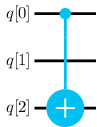

CNOT302 = [I I b0*b0']+[X I b1*b1']; CNOT302.name='CNOT(3,0,2)';
ibmqx.disp(CNOT302);

  ibmqx quantum gate operator

    Name  : CNOT(3,0,2)
    Qubits: 3

          <000| <001| <010| <011| <100| <101| <110| <111|
    |000>     1     0     0     0     0     0     0     0
    |001>     0     0     0     0     0     1     0     0
    |010>     0     0     1     0     0     0     0     0
    |011>     0     0     0     0     0     0     0     1
    |100>     0     0     0     0     1     0     0     0
    |101>     0     1     0     0     0     0     0     0
    |110>     0     0     0     0     0     0     1     0
    |111>     0     0     0     1     0     0     0     0


(4)  etc...

For convenience, the [`ibmqx`](matlab:doc('ibmqx')) class provides a method 

`      O=`[`ibmqx`](matlab:doc('ibmqx'))`.`[`CNOT`](matlab:doc('ibmqx.CNOT'))`(s)`   or   `O=`[`ibmqx`](matlab:doc('ibmqx'))`.`[`CNOT`](matlab:doc('ibmqx.CNOT'))`(N,c,t)`

which creates $CNOT$ operators of arbitrary layout.

*1.2.4   Other Gates Provided by FockBox' *[`ibmqx`](matlab:doc('ibmqx'))* Class*

The gates described in this section are usually not realizable by the IBM QX hardware! They are provided for simulating different or even hypothetical quantum computers, or just for convenience.

(1) Universal multi-qubit gate:

The [`ibmqx`](matlab:doc('ibmqx')) class supports arbitrary multi-qubit operators. All you need is a $2^N\times 2^N$ unitary operator matrix $M$. Passing such a matrix to the 

`      O=`[`ibmqx`](matlab:doc('ibmqx'))`.`[`U`](matlab:doc('ibmqx.U'))`(om,name)`

method will create the respective gate operator.

(2) Universal controlled gate:

The CNOT gate introduced above could also be called a "controlled Pauli-X" gate. The idea is to execute the gate operation only if the control qubit is $|1\rangle$. We can extend this to controlling *any* gate and to using *more than one control*. When using multiple controls, the gate operation shall only be executed, if *all* of them are $|1\rangle$. To create multiply-controlled gates, the [`ibmqx`](matlab:doc('ibmqx')) class provides the method

`      O=`[`ibmqx`](matlab:doc('ibmqx'))`.`[`CU`](matlab:doc('ibmqx.CU'))`(U,s)`,

where U is an arbitrary single- or multi-qubit quantum gate operator and s specifies the layout of the controlled gate operator to be constructed. The layout parameter is a character array consisting of the following elements:

`      '*'`: position of control qubit (must appear exactly once in the array),

`      'U'`: position of gate operator to be controlled (must appear exactly once in the array), and

`      '-'`: position of "run-through" qubits (zero, one, or more several occurrences in the array).

The qubit positions in the layout specifier run from right to left, i.e., `'*-U'` means $q[2]$ is the control, $q[0]$ is the target, and $q[1]$ just runs through. The quantum gate operator created by the [`ibmqx`](matlab:doc('ibmqx'))`.`[`CU`](matlab:doc('ibmqx.CU')) method is:

       
$$O_{U,s}
= \bigotimes\limits_{i=0}^{|s|}O_{1,i}
+ \bigotimes\limits_{i=0}^{|s|}O_{2,i}$$


where $U$denotes the operator of the gate to be controlled and $s=s_{m-1}\ldots s_0$ denotes a layout specifier with $|s|=m$ characters as defined above. $U$may be the operator of a multi-qubit gate. We denote by $n_U$ the number of qubits of that gate. The operators $O_{j,i}$ are:

      $O_{1,i}=\begin{cases}
  |0\rangle\langle 0| & \mbox{if }s_i=\texttt{'*'} \\
  \bigotimes\nolimits_{k=1}^{n_U}I &  \mbox{if }s_i=\texttt{'U'} \\
  I & \mbox{if }s_i=\texttt{'-'}
\end{cases}$      and      $O_{2,i}=\begin{cases}
  |1\rangle\langle 1| & \mbox{if }s_i=\texttt{'*'} \\
  U &  \mbox{if }s_i=\texttt{'U'} \\
  I & \mbox{if }s_i=\texttt{'-'}
\end{cases}$.

Now let's create some controlled gates:

ibmqx.disp(ibmqx.CU(X,'U*' )); % This is the CNOT201 from above

  ibmqx quantum gate operator

    Name  : (Pauli-X)*
    Qubits: 2

         <00| <01| <10| <11|
    |00>    1    0    0    0
    |01>    0    0    0    1
    |10>    0    0    1    0
    |11>    0    1    0    0


ibmqx.disp(ibmqx.CU(H,'*-U')); % A Hadamard gate at q[0] controlled by q[2]

  ibmqx quantum gate operator

    Name  : *-(Hadamard)
    Qubits: 3

            <000|   <001|   <010|   <011|   <100|   <101|   <110|   <111|
    |000>       1       0       0       0       0       0       0       0
    |001>       0       1       0       0       0       0       0       0
    |010>       0       0       1       0       0       0       0       0
    |011>       0       0       0       1       0       0       0       0
    |100>       0       0       0       0  0.7071  0.7071       0       0
    |101>       0       0       0       0  0.7071 -0.7071       0       0
    |110>       0       0       0       0       0       0  0.7071  0.7071
    |111>       0       0       0       0       0     

Calls to the [`ibmqx`](matlab:doc('ibmqx'))`.`[`U`](matlab:doc('ibmqx.U')) method can be nested to construct multiply controlled gate operators. Here are four versions of a negator controlled by two qubits (also called the CCNOT or Toffoli gate):

ibmqx.disp(ibmqx.CU(ibmqx.CU(X,'*U'),'*U'));

  ibmqx quantum gate operator

    Name  : *(*(Pauli-X))
    Qubits: 3

          <000| <001| <010| <011| <100| <101| <110| <111|
    |000>     1     0     0     0     0     0     0     0
    |001>     0     1     0     0     0     0     0     0
    |010>     0     0     1     0     0     0     0     0
    |011>     0     0     0     1     0     0     0     0
    |100>     0     0     0     0     1     0     0     0
    |101>     0     0     0     0     0     1     0     0
    |110>     0     0     0     0     0     0     0     1
    |111>     0     0     0     0     0     0     1     0


ibmqx.disp(ibmqx.CU(ibmqx.CU(X,'*U'),'U*'));

  ibmqx quantum gate operator

    Name  : (*(Pauli-X))*
    Qubits: 3

          <000| <001| <010| <011| <100| <101| <110| <111|
    |000>     1     0     0     0     0     0     0     0
    |001>     0     1     0     0     0     0     0     0
    |010>     0     0     1     0     0     0     0     0
    |011>     0     0     0     1     0     0     0     0
    |100>     0     0     0     0     1     0     0     0
    |101>     0     0     0     0     0     0     0     1
    |110>     0     0     0     0     0     0     1     0
    |111>     0     0     0     0     0     1     0     0


ibmqx.disp(ibmqx.CU(ibmqx.CU(X,'U*'),'*U'));

  ibmqx quantum gate operator

    Name  : *((Pauli-X)*)
    Qubits: 3

          <000| <001| <010| <011| <100| <101| <110| <111|
    |000>     1     0     0     0     0     0     0     0
    |001>     0     1     0     0     0     0     0     0
    |010>     0     0     1     0     0     0     0     0
    |011>     0     0     0     1     0     0     0     0
    |100>     0     0     0     0     1     0     0     0
    |101>     0     0     0     0     0     0     0     1
    |110>     0     0     0     0     0     0     1     0
    |111>     0     0     0     0     0     1     0     0


ibmqx.disp(ibmqx.CU(ibmqx.CU(X,'U*'),'U*'));

  ibmqx quantum gate operator

    Name  : ((Pauli-X)*)*
    Qubits: 3

          <000| <001| <010| <011| <100| <101| <110| <111|
    |000>     1     0     0     0     0     0     0     0
    |001>     0     1     0     0     0     0     0     0
    |010>     0     0     1     0     0     0     0     0
    |011>     0     0     0     0     0     0     0     1
    |100>     0     0     0     0     1     0     0     0
    |101>     0     0     0     0     0     1     0     0
    |110>     0     0     0     0     0     0     1     0
    |111>     0     0     0     1     0     0     0     0


Note that two of these are identical. We will come back to the Toffoli gate later.

## **2   Quantum Circuits**

2.1   Mathematical Description

The function of an $N$-qubit quantum circuit is described by a product

      
$$O = O_{M}\cdot\ldots\cdot O_2\cdot O_1$$


of operators, where $M$ denotes the number of steps or "slots" of the circuit. Each slot operator $O_m$ is defined by a unitary $2^N\times 2^N$ matrix. If slot $m$ only contains single-qubit gates, the slot operator is simply the tensor product

      
$$O_m = O_{m,{N-1}}\otimes\ldots\otimes O_{m,1}\otimes O_{m,0}$$


of the single-qubit gate operators $O_{m,n}$, where the second---zero-based---index $n$ means the the operator works on qubit $q[n]$. If one or several of the slot operators work on multiple qubits, they take the place of that many single-qubit operators in the tensor product.

2.2   A Basic Coding Example: Quantum Coin Flipping

Let's flip one quantum coin. The respective circuit is:

      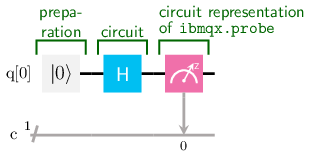

% Quantum circuit for one-qubit coin flipping
%  q[]  0 (aka. the coin)
psi =  b0    ; psi.name = 'slot 0 (initial |0> state)';                  ibmqx.disp(psi);

  ibmqx quantum state

    Name  : slot 0 (initial |0> state)
    Qubits: 1

    |0>   1
    |1>   0


psi =  H *psi; psi.name = 'slot 1 (equal superposition of |0> and |1>)'; ibmqx.disp(psi);

  ibmqx quantum state

    Name  : slot 1 (equal superposition of |0> and |1>)
    Qubits: 1

    |0> 0.7071
    |1> 0.7071


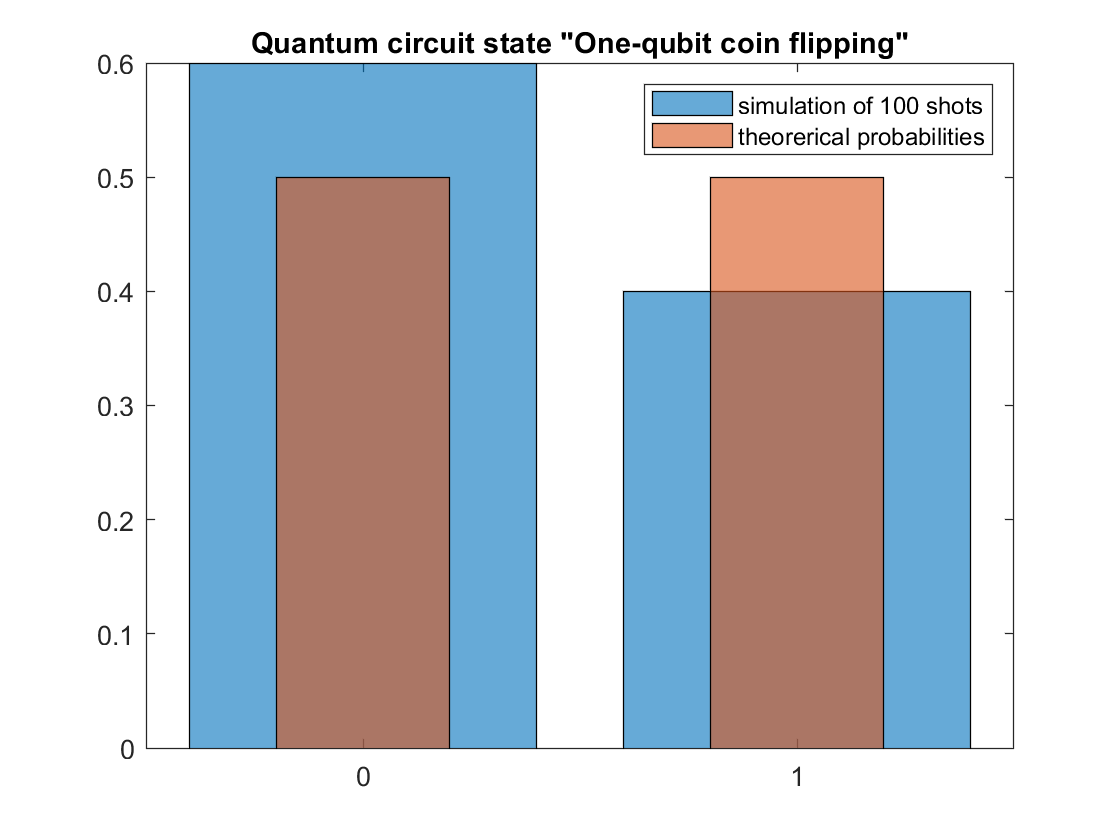

ibmqx.probe(psi,'shots',100,'name','One-qubit coin flipping');

In the resulting histogram, the odds of both possible outcomes, e.g. 0=heads and 1=tails, are roughly equal.

Now we do the same thing with two coins:

      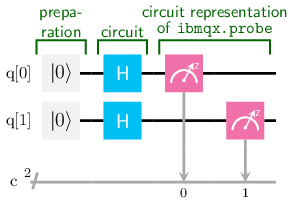

% Quantum circuit for two-qubits coin flipping
%  q[]    1  0  (aka. coin 2 and coin 1)
psi =  [ b0 b0 ]    ; psi.name = 'slot 0 (initial |00> state)';                  ibmqx.disp(psi);

  ibmqx quantum state

    Name  : slot 0 (initial |00> state)
    Qubits: 2

    |00>    1
    |01>    0
    |10>    0
    |11>    0


psi =  [ H  H  ]*psi; psi.name = 'slot 1 (equal superpositions of |0> and |1>)'; ibmqx.disp(psi);

  ibmqx quantum state

    Name  : slot 1 (equal superpositions of |0> and |1>)
    Qubits: 2

    |00>  0.5
    |01>  0.5
    |10>  0.5
    |11>  0.5


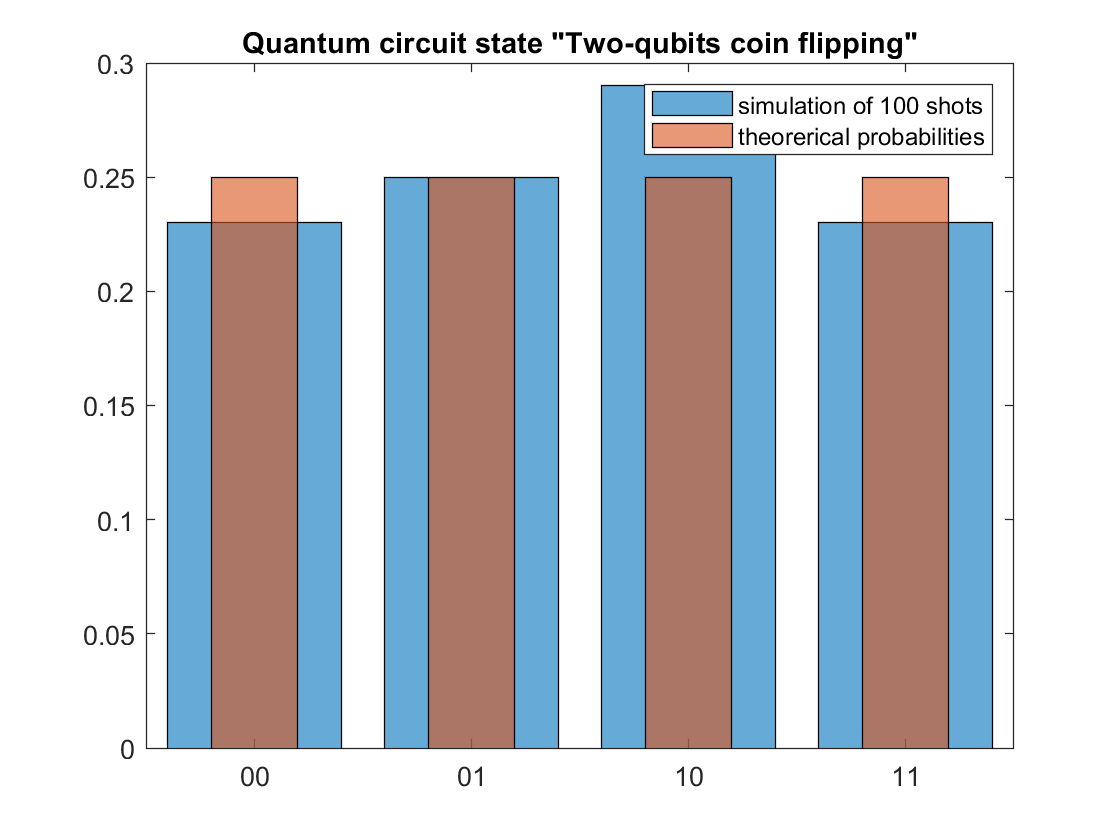

ibmqx.probe(psi,'shots',100,'name','Two-qubits coin flipping');

Just like above, the odds of the four possible outcomes---e.g. 00: coin 2 heads and coin 1 heads, 01: coin 2 heads and coin 1 tails, 10: coin 2 tails and coin 1 heads, and 11: coin 2 tails and coin 1 tails---are roughly equal.

Finally we entangle the two qubits representing our coins using the CNOT gate:

      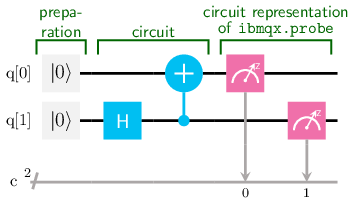

% Quantum circuit for two entangled qubits coin flipping
%  q[]    1  0  (aka. coin 2 and coin 1)
psi =  [ b0 b0 ]    ; psi.name = 'slot 0 (initial |00> state)';          ibmqx.disp(psi);

  ibmqx quantum state

    Name  : slot 0 (initial |00> state)
    Qubits: 2

    |00>    1
    |01>    0
    |10>    0
    |11>    0


psi =  [ H  I  ]*psi; psi.name = 'slot 1 (equal superposition in q[1])'; ibmqx.disp(psi);

  ibmqx quantum state

    Name  : slot 1 (equal superposition in q[1])
    Qubits: 2

    |00> 0.7071
    |01>    0
    |10> 0.7071
    |11>    0


psi =  CNOT210  *psi; psi.name = 'slot 2 (qubits entangled)';            ibmqx.disp(psi);

  ibmqx quantum state

    Name  : slot 2 (qubits entangled)
    Qubits: 2

    |00> 0.7071
    |01>      0
    |10>      0
    |11> 0.7071


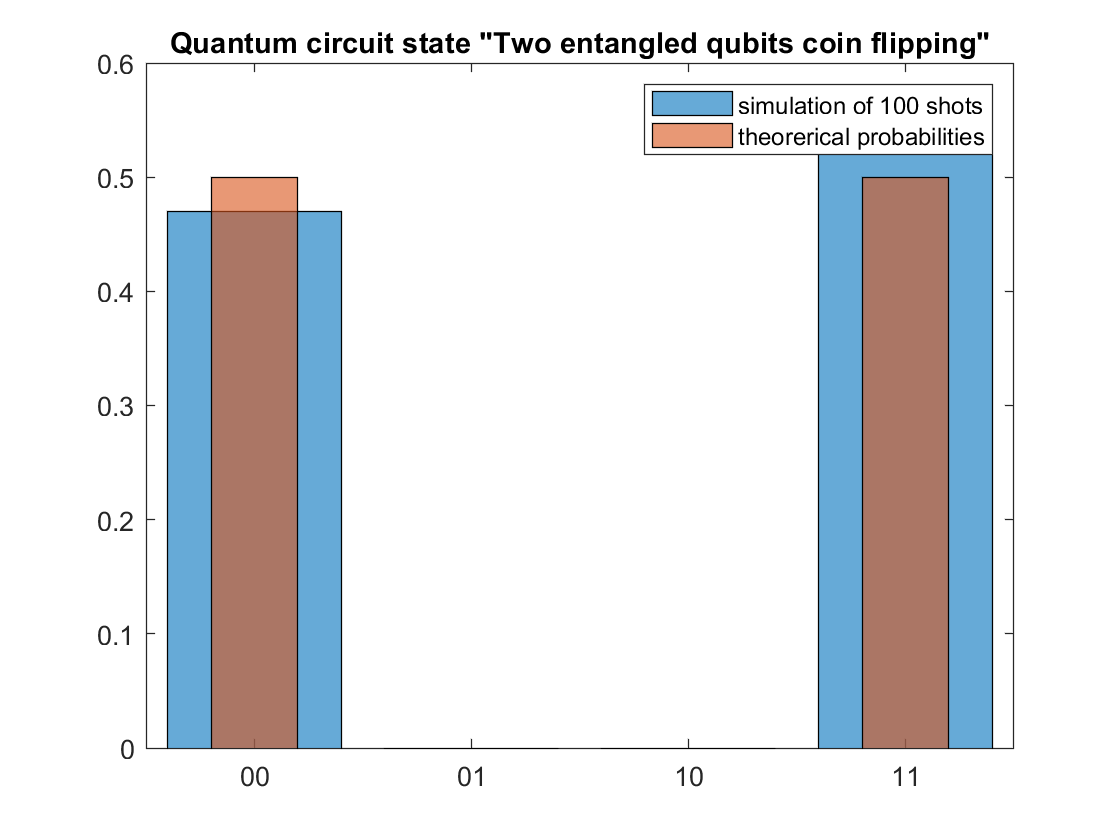

ibmqx.probe(psi,'shots',100,'name','Two entangled qubits coin flipping');

As we see, this brings forth a "magic" connection between the coins. The are either both heads ort both tails, nothing else is possible... :)

## 3   An Advanced Coding Example: The Toffoli Gate (CCNOT)

As explained above, the Toffoli or CCNOT gate is a controlled negator with two controlling qubits and one target qubit. Its circuit representation is

      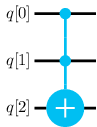

The controlling qubits are $q[0]$ and $q[1]$, the target is $q[2]$ (other combinations are possible). The function of the gate is to flip $q[2]$ iff $q[0]$ and $q[1]$ are both $|1\rangle$ and to leave $q[2]$ alone otherwise. The respective operator matrix is

      $CCNOT_{3,\{0,1\},2}\doteq\pmatrix{
  \mathbf{1} & 0 & 0 & 0 & 0 & 0 & 0 & 0 \cr
  0 & \mathbf{1} & 0 & 0 & 0 & 0 & 0 & 0 \cr
  0 & 0 & \mathbf{1} & 0 & 0 & 0 & 0 & 0 \cr
  0 & 0 & 0 & 0 & 0 & 0 & 0 & \mathbf{1} \cr
  0 & 0 & 0 & 0 & \mathbf{1} & 0 & 0 & 0 \cr
  0 & 0 & 0 & 0 & 0 & \mathbf{1} & 0 & 0 \cr
  0 & 0 & 0 & 0 & 0 & 0 & \mathbf{1} & 0 \cr
  0 & 0 & 0 & \mathbf{1} & 0 & 0 & 0 & 0
}$.

**3.1   Building the Toffoli Gate on IBM QX**

As IBM QX does not natively support the Toffoli gate, it must be implemented as a circuit of elementary gates as follows [1]

      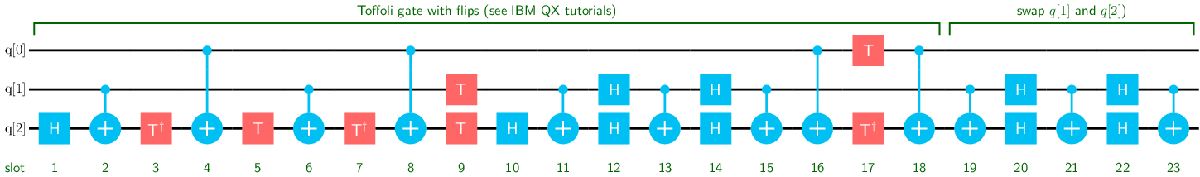

We simulate the function of this quantum cicuit by computing the resulting operator using FookBox. To this end, we first get the two required CNOT gates from the library:

CNOT302 = ibmqx.CNOT(3,0,2); % CNOT gate operator (control: q[0], target: q[2])
CNOT312 = ibmqx.CNOT(3,1,2); % CNOT gate operator (control: q[1], target: q[2])

Then, we compose the $CCNOT_{3,\{0,1\},2}$ gate operator. Note that the quantum circuit reads from left to right, but the respective operators must be multiplied from right to left.

% Quantum circuit for CCNOT gate (controls: q[0] and q[1], target: q[2])
%    q[]  2  1  0
CCNOT =   CNOT312   ...  % slot 23 --,
      * [ H  H  I ] ...  % slot 22   |
      *   CNOT312   ...  % slot 21   |
      * [ H  H  I ] ...  % slot 20   | swap q[1] and q[2]
      *   CNOT312   ...  % slot 19   |
      *   CNOT302   ...  % slot 18 --|
      * [ T' I  T ] ...  % slot 17   |
      *   CNOT302   ...  % slot 16   |
      *   CNOT312   ...  % slot 15   |
      * [ H  H  I ] ...  % slot 14   |
      *   CNOT312   ...  % slot 13   |
      * [ H  H  I ] ...  % slot 12   |
      *   CNOT312   ...  % slot 11   |
      * [ H  I  I ] ...  % slot 10   | Toffoli gate with flips from [1]
      * [ T  T  I ] ...  % slot 9    |
      *   CNOT302   ...  % slot 8    |
      * [ T' I  I ] ...  % slot 7    |
      *   CNOT312   ...  % slot 6    |
      * [ T  I  I ] ...  % slot 5    |
      *   CNOT302   ...  % slot 4    |
      * [ T' I  I ] ...  % slot 3    |
      *   CNOT312   ...  % slot 2    |
      * [ H  I  I ];     % slot 1  --'
CCNOT = round(CCNOT*1e10)*1e-10; % Mildly round-off numeric imprecision
CCNOT.name = 'Toffoli gate (controls: q[0] and q[1], target: q[2])';
ibmqx.disp(CCNOT); % disp(CCNOT) displays the underlying fockobj

  ibmqx quantum gate operator

    Name  : Toffoli gate (controls: q[0] and q[1], target: q[2])
    Qubits: 3

          <000| <001| <010| <011| <100| <101| <110| <111|
    |000>     1     0     0     0     0     0     0     0
    |001>     0     1     0     0     0     0     0     0
    |010>     0     0     1     0     0     0     0     0
    |011>     0     0     0     0     0     0     0     1
    |100>     0     0     0     0     1     0     0     0
    |101>     0     0     0     0     0     1     0     0
    |110>     0     0     0     0     0     0     1     0
    |111>     0     0     0     1     0     0     0     0


**3.2   Doing Some Boolean Logic with Quantum Gate**

Now we simulate a quantum circuit computing $q[2]=q[0]\cdot q[1]$, i.e. the conjuction of the control qubits. The circuit starts in state $|\psi\rangle = |000\rangle$, i.e., all qubits are zero (preparation). To get the whole truth table at once, we use the Hadamard gate on the control qubits which gets them into a superposition state (slot 1). In slot 2, the Toffoli gate computes the conjunction.

% Quantum circuit for q[2] = q[0] AND q[1]
%  q[]  2  1  0
psi = [b0 b0 b0]    ; psi.name = 'preparation';                   %ibmqx.disp(psi);
psi = [ I H  H ]*psi; psi.name = 'slot 1';                        %ibmqx.disp(psi);
psi =   CCNOT   *psi; psi.name = 'slot 2: q[2] = AND(q[1],q[2])'; %ibmqx.disp(psi);

As we execute the circuit step by step, the operations are in forward order. Uncomment the `ibmqx.disp` commands watch the state of the cicuit evolve. Now let's se what we have got...

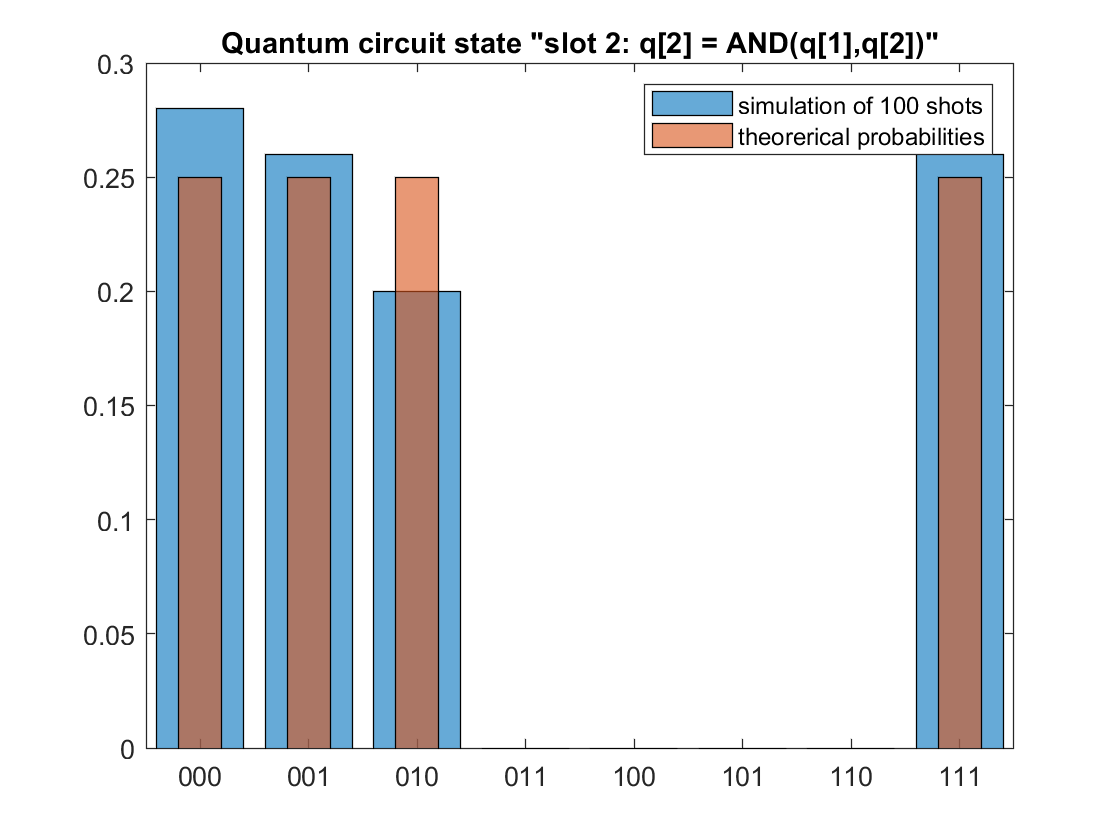

ibmqx.probe(psi,'shots',100);

... the whole truth table. Note that the result $q[1]\cdot q[0]$ is in the leftmost position.

The sixteen dyadic Boolean logic functions can be simulated by

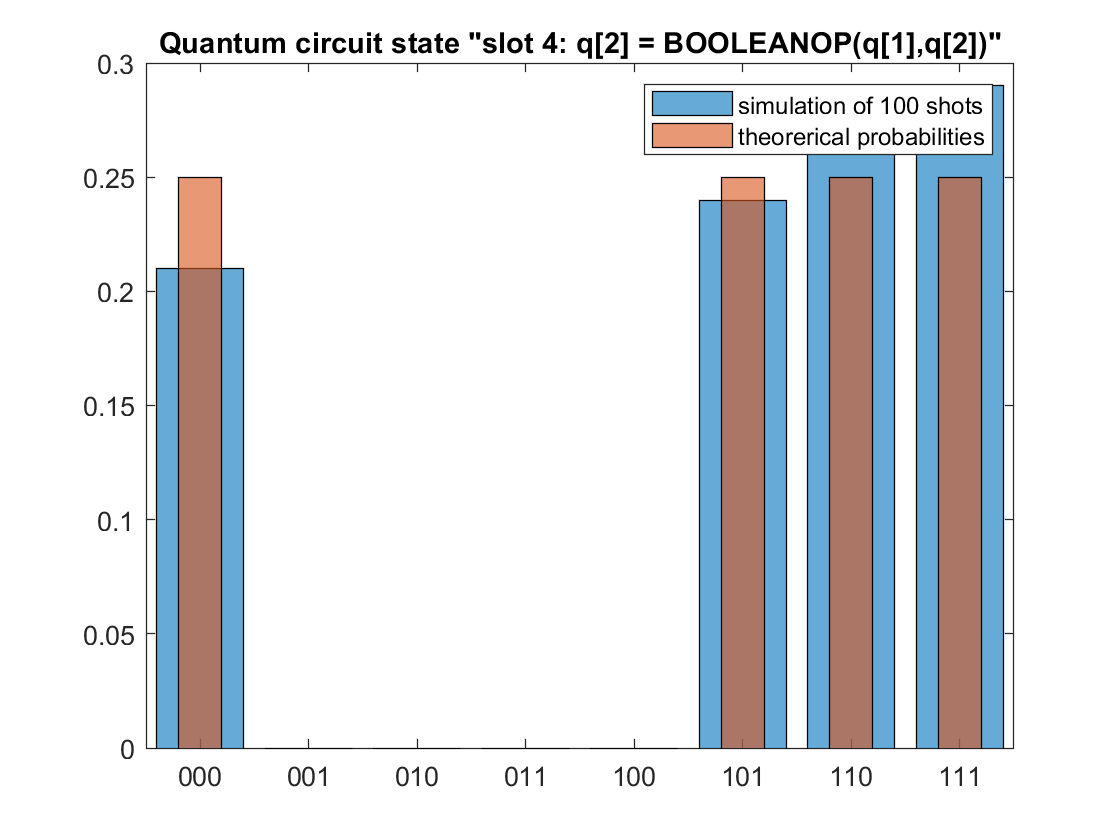

% Quantum circuit for q[2] = BOOLEANOP(q[0],q[1])
G1 = I; % in {I,X}
G2 = X; % in {I,X}
G3 = X; % in {I,X}
G4 = X; % in {I,X}

%  q[]  2  1  0
psi = [b0 b0 b0]    ; psi.name = 'preparation';                         %ibmqx.disp(psi);
psi = [G1 G2 G3]*psi; psi.name = 'slot 1';                              %ibmqx.disp(psi);
psi = [ I H  H ]*psi; psi.name = 'slot 2';                              %ibmqx.disp(psi);
psi =   CCNOT   *psi; psi.name = 'slot 3';                              %ibmqx.disp(psi);
psi = [G4 G2 G3]*psi; psi.name = 'slot 4: q[2] = BOOLEANOP(q[1],q[2])'; %ibmqx.disp(psi);
ibmqx.probe(psi,'shots',100);

The preset operators $\texttt{G}_1 = I$ and $\texttt{G}_2,\texttt{G}_3,\texttt{G}_4 = X$ effect to the Boolean adjunction (OR). Modify $\texttt{G}_i\in\{I,X\}$ to simulate other functions.

## References

[1] IBM Q Experience. Online: [https://quantumexperience.ng.bluemix.net,](https://quantumexperience.ng.bluemix.net,) Retrieved Aug. 15, 2018.

[2] M. Wolff, G. Wirsching, M. Huber, P. beim Graben, R. Römer, and I. Schmitt: A Fock Space Toolbox and Some Applications in Computational Cognition (Preprint). DOI: [10.13140/RG.2.2.10025.70245](http://www.doi.org/10.13140/RG.2.2.10025.70245), May 2018.

[3] M. Wolff: The `tikz-quantumgates` Package: Drawing Quantum Circuits with TikZ. Technical report, BTU Cottbus-Senfternberg. DOI: [10.13140/RG.2.2.35696.71685](http://www.doi.org/10.13140/RG.2.2.35696.71685), Aug. 2018.